# Well-being cost function

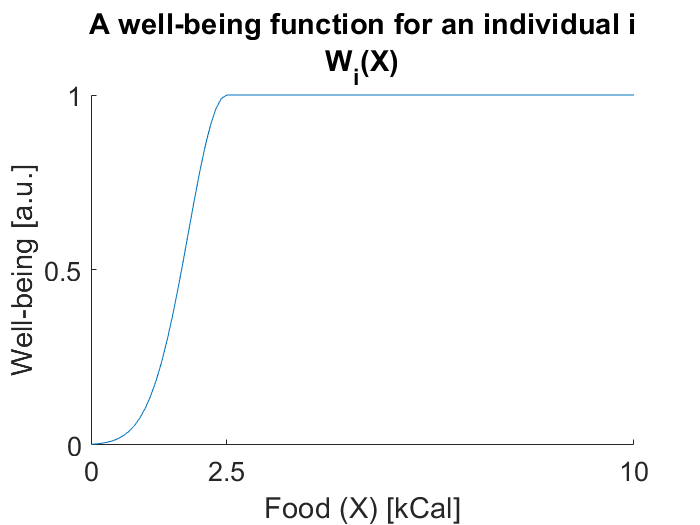

food_per_day = 0:0.1:10; %in kilo calories; 
X = food_per_day;
W = exp(-(X-2.5).^2)./1;
W(X>2.5) = 1;

figure;
plot(X,W);
yticks([0,0.5,1]);
xticks([0,2.5,10]);
box off;
set(gca,'FontSize',16);
xlabel('Food (X) [kCal]');
ylabel('Well-being [a.u.]');
title({'A well-being function for an individual i','W_i(X)'},'FontSize',18);

## Maximizing several functions dependendent on the same variable.

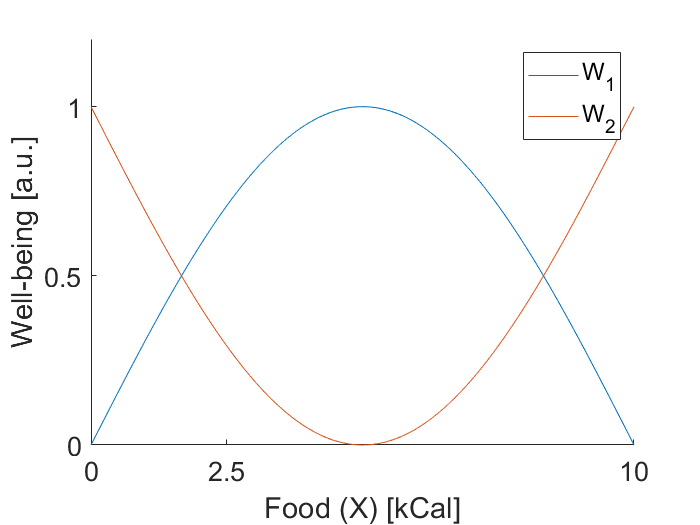

W1 = sin(X./max(X).*pi);
W2 = 1+sin(X./max(X).*pi+pi);
figure; 
plot(X,W1);
hold on;
plot(X,W2);
yticks([0,0.5,1]);
xticks([0,2.5,10]);
box off;
set(gca,'FontSize',16);
legend('W_1','W_2');
xlabel('Food (X) [kCal]');
ylabel('Well-being [a.u.]');